IMU Calibration Function. 

Scaling, misaligned, compensation of IMU values. 

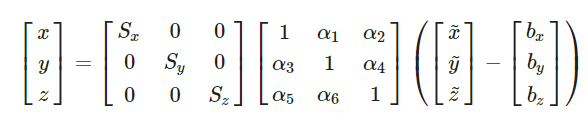

function [accX, accY, accZ, roll, pitch, yaw] = calibrateICM20689(rawAccX, rawAccY, rawAccZ, rawRoll, rawPitch, rawYaw)

% Accelerometer calibration

% Remove offset 
accXTemp = ((rawAccX) - 103.519);
accYTemp = ((rawAccY) + 42.729);
accZTemp = ((rawAccZ) - 92.2236);

% Misalignment Matrix 
alpha1Acc = 0.000498546; 
alpha2Acc = 0.00347686;
alpha3Acc = 0;
alpha4Acc = 0.00532353;
alpha5Acc = 0; 
alpha6Acc = 0; 

accX = accXTemp + accYTemp*alpha1Acc + accZTemp*alpha2Acc;
accY = accXTemp*alpha3Acc + accYTemp + accZTemp*alpha4Acc; 
accZ = accXTemp*alpha5Acc + accYTemp*alpha6Acc + accZTemp; 

%Scaling functions
accX = accX/1669.36;
accY = accY/1668.9;
accZ = accZ/1686.46 - 9.8172; %remove graviational force
%Gyroscope calibration 

%Remove offset
rollTemp = rawRoll + 74.9;
pitchTemp = rawPitch  - 190.96;
yawTemp = rawRoll - 20.5908;

% Misalignment Matrix 
alpha1Gyro = 0.0962799; 
alpha2Gyro = 0.540795;
alpha3Gyro = -0.167719;
alpha4Gyro = 0.112196;
alpha5Gyro = -0.199794; 
alpha6Gyro = 0.0435025; 

roll = rollTemp + pitchTemp*alpha1Gyro + yawTemp*alpha2Gyro;
pitch = rollTemp*alpha3Gyro + pitchTemp + yawTemp*alpha4Gyro; 
yaw = rollTemp*alpha5Gyro + pitchTemp*alpha6Gyro + yawTemp; 

%Scaling 
roll = roll/131.226;
pitch = pitch/137.732;
yaw = yaw/145.342;

end